% 参数设定
p0 = 0.10;   % 次品率
Right_Threshold = 0.05;  % 右尾检验显著性水平（拒收）
Left_Threshold = 0.10;   % 左尾检验显著性水平（接收）
E = 0.05;    % 允许误差

% 临界值计算 (正态近似)
Z_right = norminv(1 - Right_Threshold);  % 右尾临界值（拒收）
Z_left = norminv(Left_Threshold);        % 左尾临界值（接收）

% 样本量计算（经验公式）
n_right = (Z_right * sqrt(p0 * (1 - p0)) / E)^2;  % 95%信度样本量
n_left = (Z_left * sqrt(p0 * (1 - p0)) / E)^2;    % 90%信度样本量

% 计算拒收和接收的临界值
n = ceil(n_right);  % 取大于等于n_right的最小整数作为样本量
X_critical_reject = n * p0 + Z_right * sqrt(n * p0 * (1 - p0));  % 拒收临界值
X_critical_reject = round(X_critical_reject);
n_1 = ceil(n_left);
X_critical_accept = n * p0 + Z_left * sqrt(n * p0 * (1 - p0));   % 接收临界值
X_critical_accept = fix(X_critical_accept);
% 输出结果
fprintf('第一问第一题样本量 n: %.0f\n', n);

第一问第一题样本量 n: 98


fprintf('在 95%% 信度下，拒收临界次品数量: %.2f\n', X_critical_reject);

在 95% 信度下，拒收临界次品数量: 15.00


fprintf('第一问第二题样本量 n: %.0f\n', n_1);

第一问第二题样本量 n: 60


fprintf('在 90%% 信度下，接收临界次品数量: %.2f\n', X_critical_accept);

在 90% 信度下，接收临界次品数量: 5.00



% 可视化
x = 0:n;  % 次品数量范围
p_reject = normcdf(x, n * p0, sqrt(n * p0 * (1 - p0)));  % 拒收概率
p_accept = normcdf(x, n * p0, sqrt(n * p0 * (1 - p0)));  % 接收概率

figure;
plot(x, p_reject, 'r-', 'LineWidth', 2); 
xlabel('次品数量');
ylabel('信度');
legend('拒收概率', '接收概率');

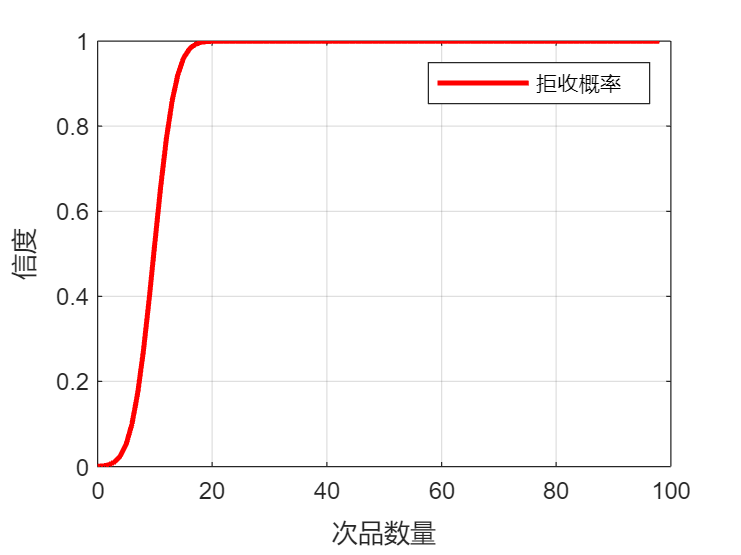

%title('抽样检验方案');
grid on;

plot(x, p_accept, 'b-', 'LineWidth', 2);
xlabel('次品数量');
ylabel('信度');
legend('接收概率', '接收概率');

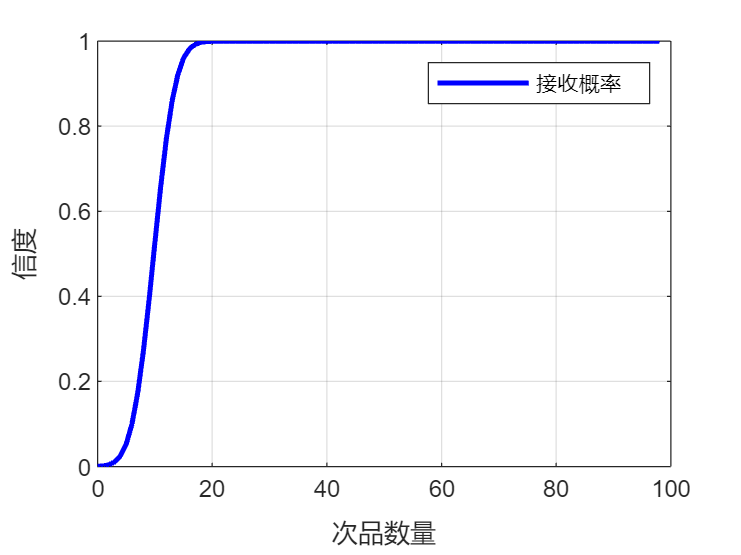

%title('抽样检验方案');
grid on;